## Задача 1

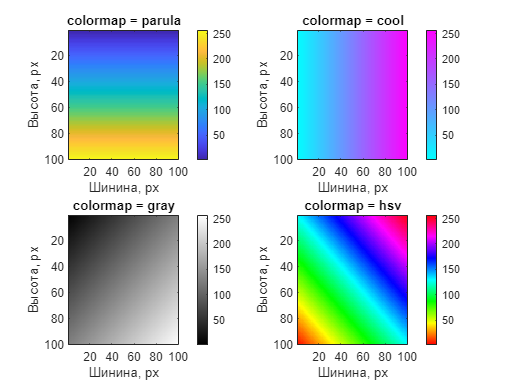

N = 100;
A1 = zeros(N);
for i = 1 : N
    for j = 1 : N
        A1(i,j) = 255 / N * i;
    end
end
A2 = A1';
A3 = symdec(100, -1);
for i = 1 : N
    for j = 1 : N
        A3(i,j) = A3(i,j)/N;
    end
end
B = A1;
B = (A1 + A1')/2;
A4 = B;
for i=1:N
    A4(:,i) = B(:,100-i+1);
end
A4 = A4';

f1 = figure();

ax1 = subplot(2,2,1);
image(A1)
colormap(ax1, 'parula');
colorbar
title('colormap = parula')
xlabel('Шинина, px')
ylabel('Высота, px')

ax2 = subplot(2,2,2);
image(A2)
colormap(ax2, 'cool');
colorbar
title('colormap = cool')
xlabel('Шинина, px')
ylabel('Высота, px')

ax3 = subplot(2,2,3);
image(B)
colormap(ax3, 'gray');
colorbar
title('colormap = gray')
xlabel('Шинина, px')
ylabel('Высота, px')

ax4 = subplot(2,2,4);
image(A4)
colormap(ax4, 'hsv');
colorbar
title('colormap = hsv')
xlabel('Шинина, px')
ylabel('Высота, px')

saveas(f1, 'e1.png')

## Задача 2

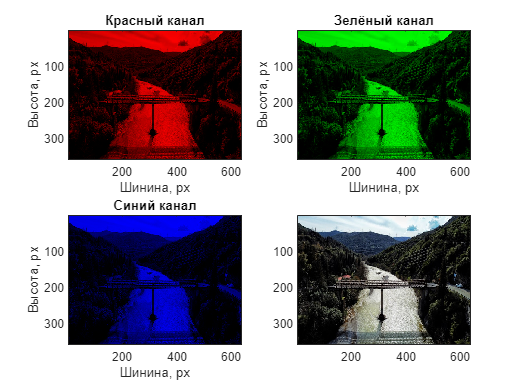

mem = imread('2.jpg');
black = zeros(size(mem(:,:,1)));

red = cat(3, mem(:,:,1), black, black);

f2 = figure();

subplot(2,2,1)
image(red)


title('Красный канал')
xlabel('Шинина, px')
ylabel('Высота, px')


green = cat(3, black, mem(:,:,2), black);
subplot(2,2,2)
image(green)

title('Зелёный канал')
xlabel('Шинина, px')
ylabel('Высота, px')

blue = cat(3, black, black, mem(:,:,3));
subplot(2,2,3)
image(blue)


title('Синий канал')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,4)
image(mem)

## Задача 3

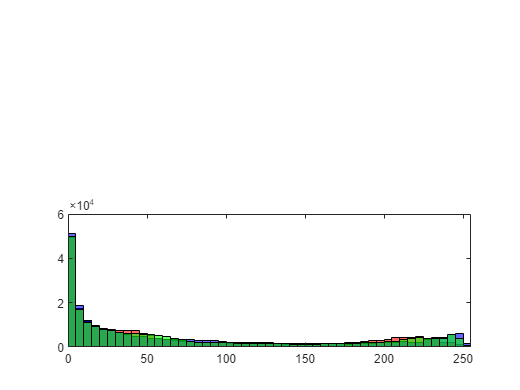

mem = imread('2.jpg');


f3 = figure();





subplot(2,1,2);
histogram(mem(:,:,1), 'FaceColor', 'red')
xlim([0, 255])
hold on

subplot(2,1,2);
histogram(mem(:,:,3), 'FaceColor', 'blue')
xlim([0, 255])

hold on

subplot(2,1,2);
histogram(mem(:,:,2), 'FaceColor', 'green')
xlim([0, 255])





saveas(f3, 'e3.png')

Задача 4

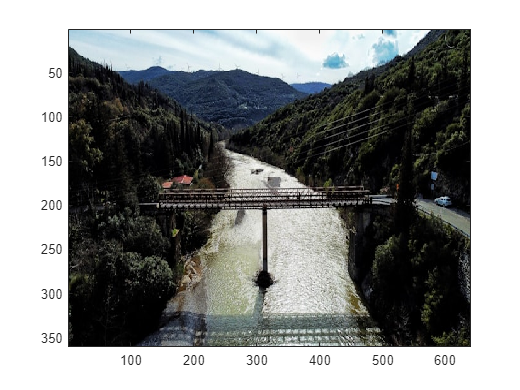

f4 = figure();

n=3;

im = imread("2.jpg");

image(im)

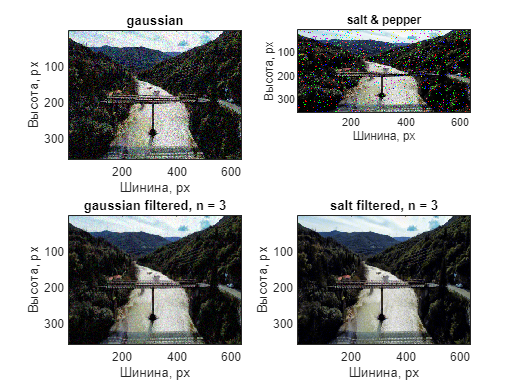


gauss = imnoise(im,"gaussian");
salt = imnoise(im,"salt & pepper");

subplot(2,2,1)
image(gauss)
title("gaussian")
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(3,2,2)
image(salt)
title("salt & pepper")
xlabel('Шинина, px')
ylabel('Высота, px')

r = gauss(:,:,1);
g = gauss(:,:,2);
b = gauss(:,:,3);

gaussian_filtered = im;
gaussian_filtered(:,:,1) = medfilt(r, n);
gaussian_filtered(:,:,2) = medfilt(g, n);
gaussian_filtered(:,:,3) = medfilt(b, n);


r1 = salt(:,:,1);
g1 = salt(:,:,2);
b1 = salt(:,:,3);
salt_filtered(:,:,1) = medfilt(r1, n);
salt_filtered(:,:,2) = medfilt(g1, n);
salt_filtered(:,:,3) = medfilt(b, n);

subplot(2,2,3)
image(gaussian_filtered)
title('gaussian filtered, n = 3')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,4)
image(uint8(salt_filtered))
title('salt filtered, n = 3')
xlabel('Шинина, px')
ylabel('Высота, px')

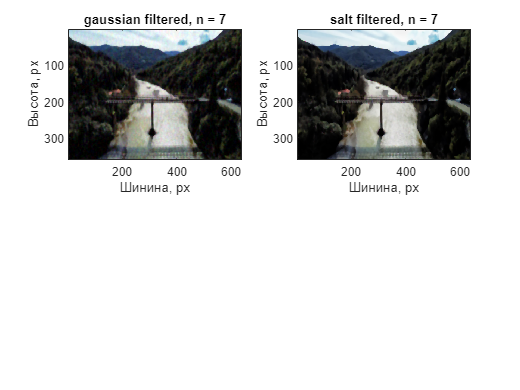



n=7;
r = gauss(:,:,1);
g = gauss(:,:,2);
b = gauss(:,:,3);

gaussian_filtered7 = im;
gaussian_filtered7(:,:,1) = medfilt(r, n);
gaussian_filtered7(:,:,2) = medfilt(g, n);
gaussian_filtered7(:,:,3) = medfilt(b, n);


r = salt(:,:,1);
g = salt(:,:,2);
b = salt(:,:,3);
salt_filtered(:,:,1) = medfilt(r, n);
salt_filtered(:,:,2) = medfilt(g, n);
salt_filtered(:,:,3) = medfilt(b, n);


f = figure();
subplot(2,2,1)
image(gaussian_filtered7)
title('gaussian filtered, n = 7')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,2)
image(uint8(salt_filtered))
title('salt filtered, n = 7')
xlabel('Шинина, px')
ylabel('Высота, px')


s0 =std_dev(gaussian_filtered(:,:,1), im(:,:,1))

s0 = 7.5727